# ** ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_slcm.mlx
    ------------
    This code solves the stochastic life cycle model using backward induction.

%}

## Model: Stochastic Life Cycle Model.

The representative consumer is born in period $0$ and lives up to $T-1$. Her working life is from period $0$ to $t_r-1$, where she receives exogenous labor income, $y_t$. From period $t_r$ onward, she is retired and receives a pension equal to some fraction, $0<\kappa<1$, of her labor income in the last period of her working life. She maximizes lifetime utility by choosing consumption and savings, subject to a dynamic budget constraint in each period. Her optimization problem is:


$$\underset{\{c_t\}_{t=1}^{T-1},\{a_{t+1}\}_{t=0}^{T-1}}{\text{max }} \mathbb{E}_0\left(U\right) =  \mathbb{E}_0\left[\sum_{t=1}^{T-1} \beta^{t} \frac{c_t^{1-\sigma}}{1-\sigma}\right] \text{ ,}$$


 
$$\text{s.t. } a_{t+1} = (1+r)(a_t+y_t-c_t)  \ , $$



$$y_t = \begin{cases}
		\text{exp}(\rho \ \text{log} \ y_{t-1} + \epsilon_t) & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


for all $t = 0, 1, ..., T-1$ and where $|\rho|<1$ and $\epsilon_t\sim\mathcal{N}(0,\sigma^2)$. The consumer has an initial wealth endowment, $a_0\geq0$, and the real interest rate, $r$, is fixed. You will gradually extend, solve, and simulate this model. When simulating the model, initialize the state variables, including age: for the endogenous state variables, assume equal probabilities for each state; for any exogenous Markov process, draw from the stationary distribution. In each simulation, you must have a panel of 1000 consumers over 30 periods. 

## Recursive Formulation.

The recursive formulation  is


$$V_t(a_t,t,y_t) = \underset{c_t, a_{t+1}}{\text{max}}\frac{c_t^{1-\sigma}}{1-\sigma} + \beta \mathbb{E}_0\left[V_{t+1}(a_{t+1},t+1,y_{t+1})\right] \ ,$$


 
$$\text{s.t. } a_{t+1} = (1+r)(a_t+y_t-c_t)  \ , $$



$$y_t = \begin{cases}
		\text{exp}(\rho \ \text{log} \ y_{t-1} + \epsilon_t) & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


The state space consists only of $a_t$ while the choice space consists of $c_t$ and $a_{t+1}$. Substituting the budget constraint into the utility function gives


$$V_t(a_t,t,y_t) = \underset{a_{t+1}}{\text{max}}\frac{\left[a_t+y_t-\frac{a_{t+1}}{1+r}\right]^{1-\sigma}}{1-\sigma} + \beta \left[V_{t+1}(a_{t+1},t+1,y_{t+1})\right] \ ,$$



$$y_t = \begin{cases}
		\text{exp}(\rho \ \text{log} \ y_{t-1} + \epsilon_t) & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


which reduces the choice space to $a_{t+1}$.

## Set up directories and paths.

clc
clear
close all

id = getenv('USERNAME'); % Gets your username.

main = strcat('/Users/apple/Documents/ps2-p2'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.

fprintf('The directory is %s \n\n',main)

The directory is /Users/apple/Documents/ps2-p2 



## Set the parameters and generate the state space.

Calls: model.m.

The grid for assets is set exogenously.

par = model.setup; % Set parameters.
par = model.gen_grids(par); % Generate the state space.

## Solve the model using Backward Induction.

Calls: solve.m and model.m.

We will solve the model using backward induction. In the last period of life, it is optimal to consume everything


$$c_T = a_T + y_T \ .$$


t = cputime;
sol = solve.lc(par); % Solve the model using Backward Induction.

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------



fprintf('\nModel solved in %0.4f seconds.\n', cputime-t)


Model solved in 9.6700 seconds.


## Simulate the model and plot the policy functions.

Calls: simulate.m and my_graph.m.

Simulate a population with heterogeneous age.

sim = simulate.lc(par,sol); % Simulate the model.

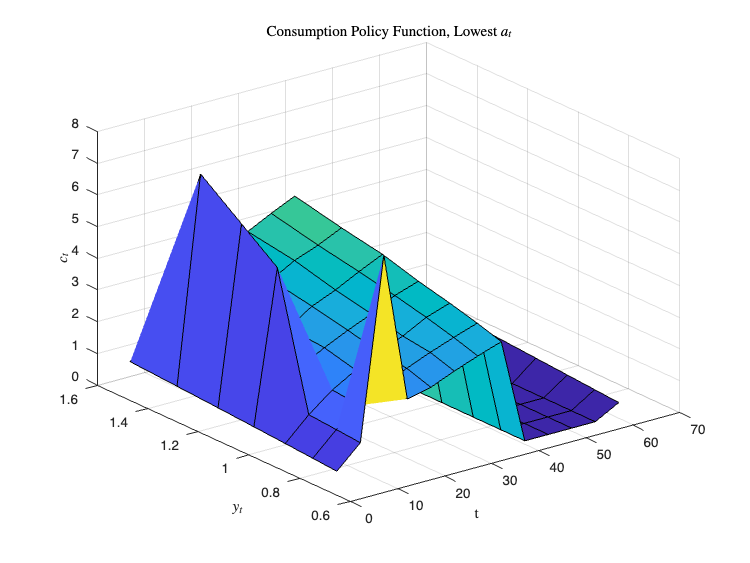

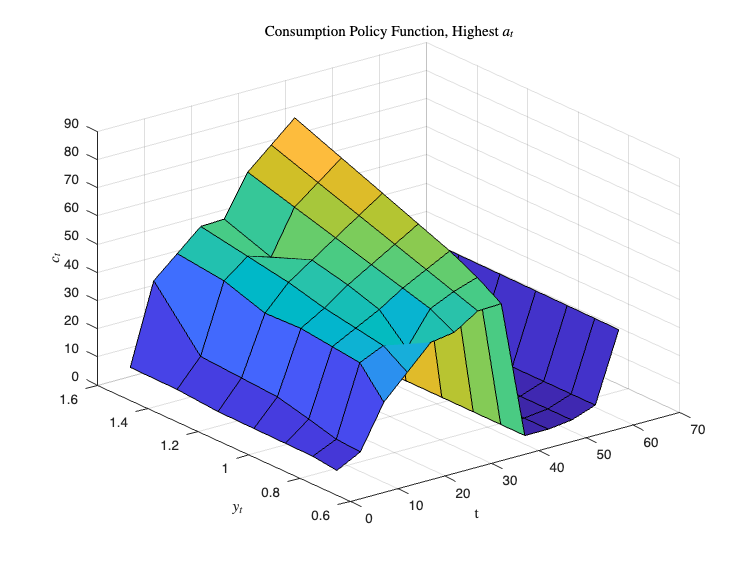

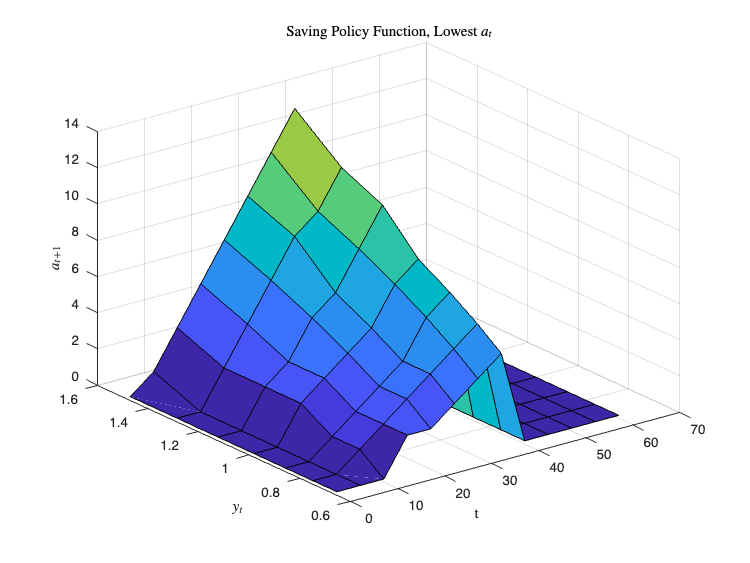

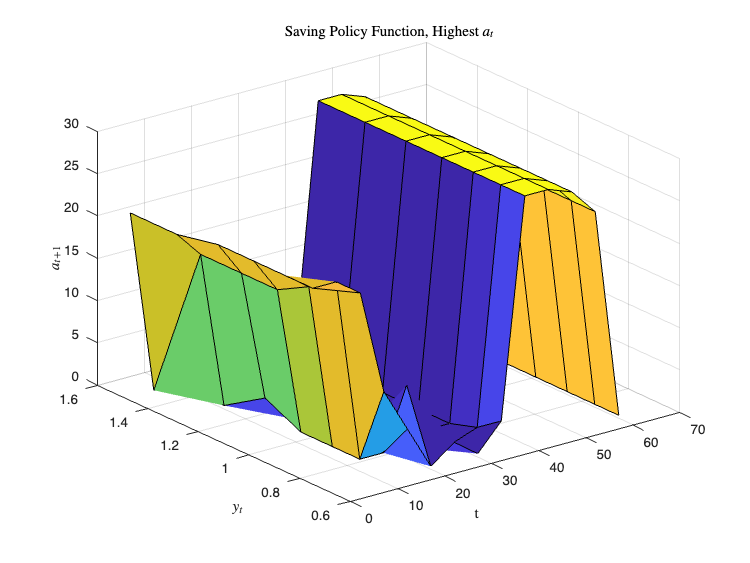

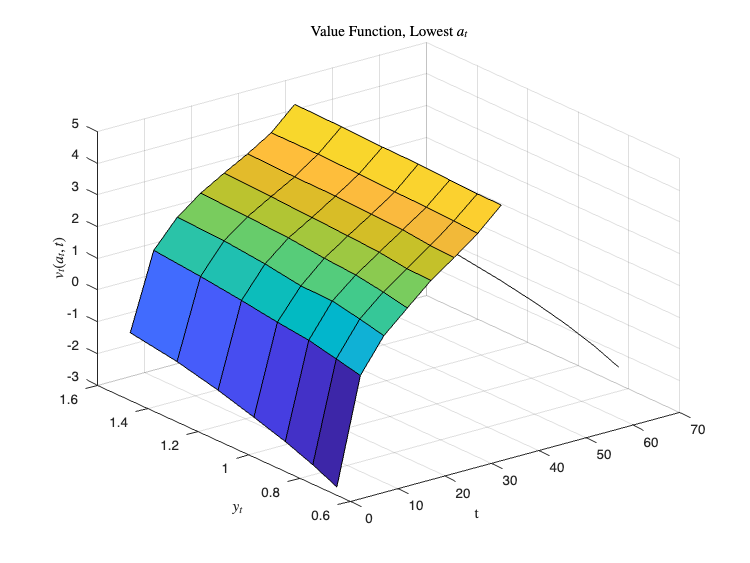

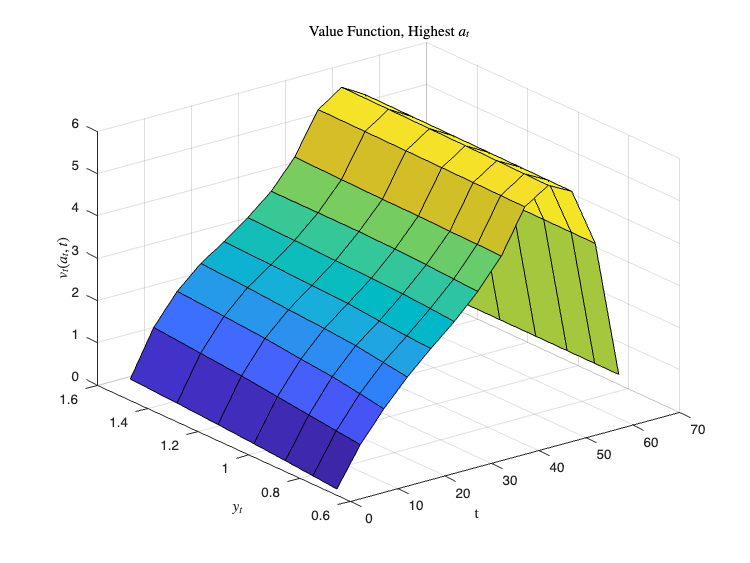

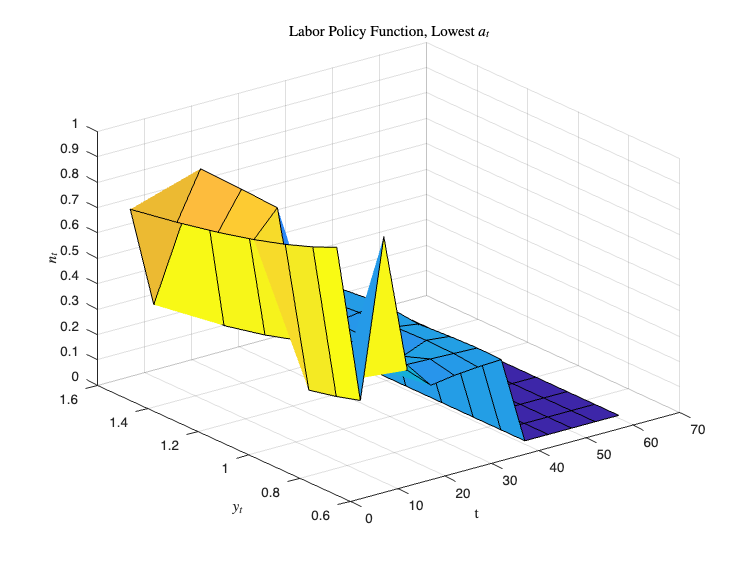

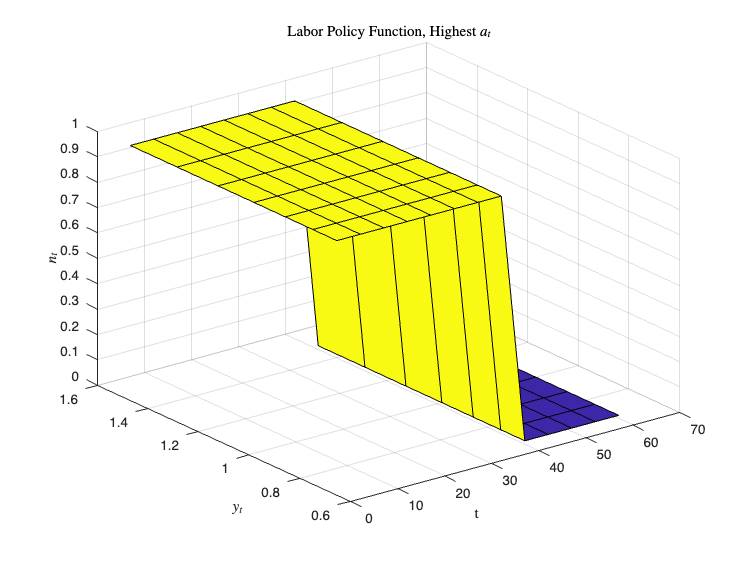

my_graph.plot_policy(par,sol,sim) % Plot the model functions and time series.

% Consumption and wealth graphs
beta_list = [0.90, 0.92, 0.94, 0.96];
gamma_list = [2.00, 3.00, 4.00, 5.00];
gamma_fixed = 2.00;
beta_fixed = 0.96;

%% === 1. GRAPHS: Varying Beta, Fixed Gamma = 2.00 ===
par0 = model.setup();
T = par0.T;
avg_c_all = nan(length(beta_list), T);
avg_a_all = nan(length(beta_list), T);

for b = 1:length(beta_list)
    par = model.setup();
    par.sigma   = gamma_fixed;
    par.beta = beta_list(b);
    par = model.gen_grids(par);
    
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);
    
    for i = 1:T
        avg_c_all(b, i) = mean(sim.csim(sim.tsim == i), 'omitnan');
        avg_a_all(b, i) = mean(sim.asim(sim.tsim == i), 'omitnan');
    end
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


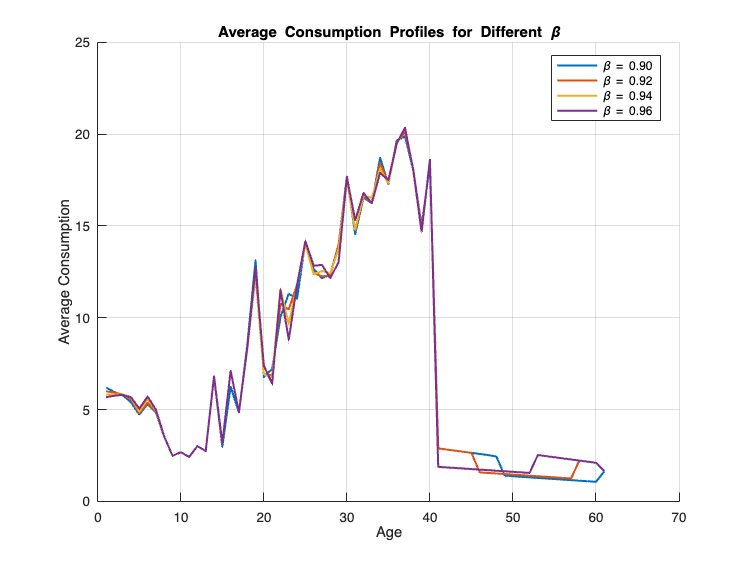


% Plot: Average Consumption
figure;
hold on;
colors = lines(length(beta_list));
for b = 1:length(beta_list)
    plot(1:T, avg_c_all(b, :), 'LineWidth', 1.5, 'Color', colors(b,:), ...
        'DisplayName', sprintf('\\beta = %.2f', beta_list(b)));
end
hold off;
xlabel('Age');
ylabel('Average Consumption');
title('Average Consumption Profiles for Different \beta');
legend('Location', 'best');
grid on;

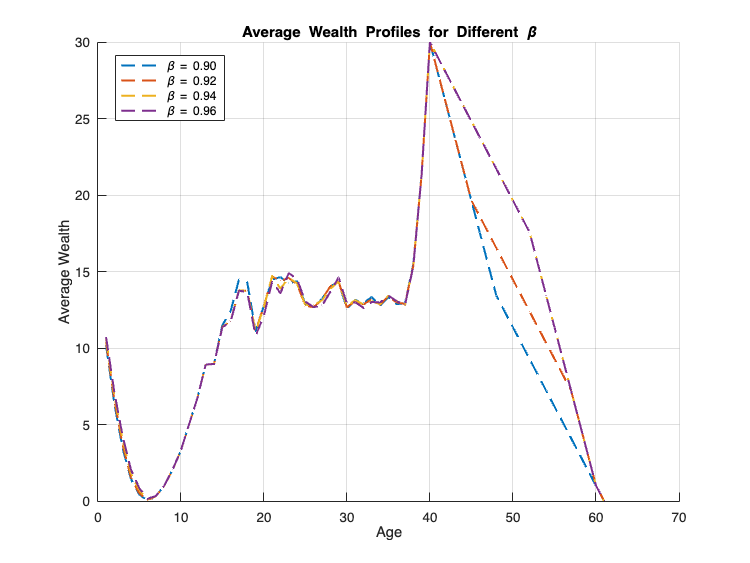


% Plot: Average Wealth
figure;
hold on;
for b = 1:length(beta_list)
    plot(1:T, avg_a_all(b, :), '--', 'LineWidth', 1.5, 'Color', colors(b,:), ...
        'DisplayName', sprintf('\\beta = %.2f', beta_list(b)));
end
hold off;
xlabel('Age');
ylabel('Average Wealth');
title('Average Wealth Profiles for Different \beta');
legend('Location', 'best');
grid on;


% === Descriptive Stats: Based on the Graph Data ===
table_beta_consumption = table();
table_beta_savings = table();

for b = 1:length(beta_list)
    lcp_c = avg_c_all(b, :)';
    lcp_a = avg_a_all(b, :)';
    
    table_beta_consumption.Beta(b) = beta_list(b);
    table_beta_consumption.Mean(b) = mean(lcp_c, 'omitnan');
    table_beta_consumption.Std(b) = std(lcp_c, 'omitnan');
    table_beta_consumption.Min(b) = min(lcp_c);
    table_beta_consumption.Max(b) = max(lcp_c);
    
    table_beta_savings.Beta(b) = beta_list(b);
    table_beta_savings.Mean(b) = mean(lcp_a, 'omitnan');
    table_beta_savings.Std(b) = std(lcp_a, 'omitnan');
    table_beta_savings.Min(b) = min(lcp_a);
    table_beta_savings.Max(b) = max(lcp_a);
end


disp("Consumption Stats – Varying Beta, Gamma = 2.00");

Consumption Stats – Varying Beta, Gamma = 2.00


disp(table_beta_consumption);

    Beta     Mean      Std       Min       Max  
    ____    ______    ______    ______    ______

     0.9    7.1927    6.0872    1.0643    19.871
    0.92    7.2173    6.0543    1.2454     20.08
    0.94    7.2504    6.0237    1.5467    20.345
    0.96    7.2546    6.0315    1.5467    20.337




disp("Wealth Stats – Varying Beta, Gamma = 2.00");

Wealth Stats – Varying Beta, Gamma = 2.00


disp(table_beta_savings);

    Beta     Mean      Std      Min     Max  
    ____    ______    ______    ___    ______

     0.9    11.094     6.912     0     29.984
    0.92    11.687    6.7967     0         30
    0.94    12.718    7.6878     0         30
    0.96    12.713    7.6695     0         30




%% === 2. GRAPHS: Varying Gamma, Fixed Beta = 0.96 ===
avg_c_all = nan(length(gamma_list), T);
avg_a_all = nan(length(gamma_list), T);

for b = 1:length(gamma_list)
    par = model.setup();
    par.sigma = gamma_list(b);
    par.beta = beta_fixed;
    par = model.gen_grids(par);
    
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);
    
    for i = 1:T
        avg_c_all(b, i) = mean(sim.csim(sim.tsim == i), 'omitnan');
        avg_a_all(b, i) = mean(sim.asim(sim.tsim == i), 'omitnan');
    end
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


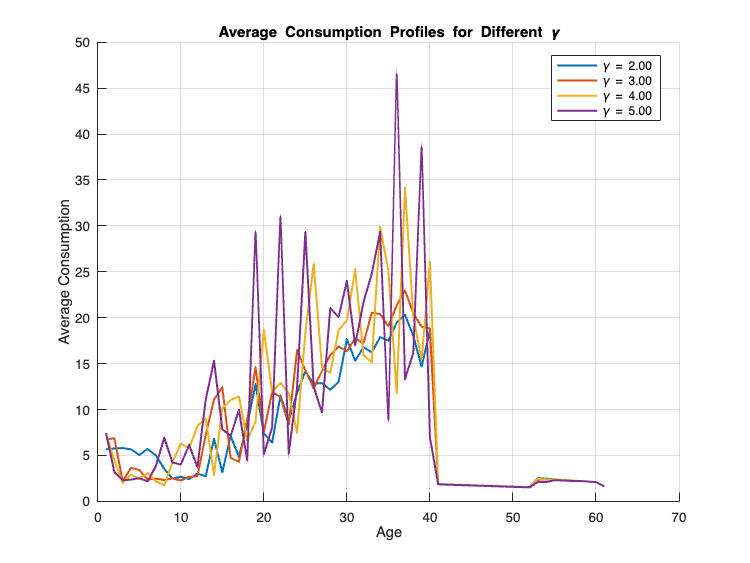


% Plot: Average Consumption
figure;
hold on;
colors = lines(length(gamma_list));
for b = 1:length(gamma_list)
    plot(1:T, avg_c_all(b, :), 'LineWidth', 1.5, 'Color', colors(b,:), ...
        'DisplayName', sprintf('\\gamma = %.2f', gamma_list(b)));
end
hold off;
xlabel('Age');
ylabel('Average Consumption');
title('Average Consumption Profiles for Different \gamma');
legend('Location', 'best');
grid on;

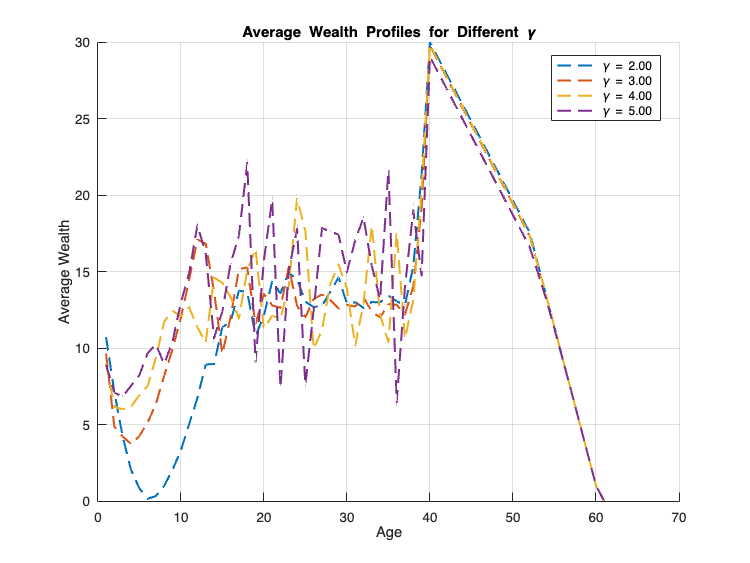


% Plot: Average Wealth
figure;
hold on;
for b = 1:length(gamma_list)
    plot(1:T, avg_a_all(b, :), '--', 'LineWidth', 1.5, 'Color', colors(b,:), ...
        'DisplayName', sprintf('\\gamma = %.2f', gamma_list(b)));
end
hold off;
xlabel('Age');
ylabel('Average Wealth');
title('Average Wealth Profiles for Different \gamma');
legend('Location', 'best');
grid on;


% === Descriptive Stats: Based on the Graph Data ===
table_gamma_consumption = table();
table_gamma_savings = table();

for b = 1:length(gamma_list)
    lcp_c = avg_c_all(b, :)';
    lcp_a = avg_a_all(b, :)';
    
    table_gamma_consumption.Gamma(b) = gamma_list(b);
    table_gamma_consumption.Mean(b) = mean(lcp_c, 'omitnan');
    table_gamma_consumption.Std(b) = std(lcp_c, 'omitnan');
    table_gamma_consumption.Min(b) = min(lcp_c);
    table_gamma_consumption.Max(b) = max(lcp_c);
    
    table_gamma_savings.Gamma(b) = gamma_list(b);
    table_gamma_savings.Mean(b) = mean(lcp_a, 'omitnan');
    table_gamma_savings.Std(b) = std(lcp_a, 'omitnan');
    table_gamma_savings.Min(b) = min(lcp_a);
    table_gamma_savings.Max(b) = max(lcp_a);
end


disp("Consumption Stats – Varying Gamma, Beta = 0.96");

Consumption Stats – Varying Gamma, Beta = 0.96


disp(table_gamma_consumption);

    Gamma     Mean      Std       Min       Max  
    _____    ______    ______    ______    ______

      2      7.2546    6.0315    1.5467    20.337
      3      7.9835    7.0503    1.5401    22.981
      4      8.9127    8.5055    1.5418    34.167
      5      9.4251    10.456     1.519    46.495




disp("Wealth Stats – Varying Gamma, Beta = 0.96");

Wealth Stats – Varying Gamma, Beta = 0.96


disp(table_gamma_savings);

    Gamma     Mean      Std      Min     Max  
    _____    ______    ______    ___    ______

      2      12.713    7.6695     0         30
      3      13.652      6.72     0     29.772
      4      14.064     6.593     0     29.833
      5      14.645    6.5656     0     29.049



% Consumption and wealth graphs
gamma_list = [1.00, 2.00, 3.00, 4.00];
nu_list = [0.5, 1.0, 1.5, 2.00];
gamma_fixed = 2.00;
nu_fixed = 0.5;

%% === 1. GRAPHS: Varying Beta, Fixed Gamma = 2.00 ===
par0 = model.setup();
T = par0.T;
avg_c_all = nan(length(gamma_list), T);
avg_a_all = nan(length(gamma_list), T);

for b = 1:length(gamma_list)
    par = model.setup();
    par.nu   = nu_fixed;
    par.gamma = gamma_list(b);
    par = model.gen_grids(par);
    
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);
    
    for i = 1:T
        avg_c_all(b, i) = mean(sim.csim(sim.tsim == i), 'omitnan');
        avg_a_all(b, i) = mean(sim.asim(sim.tsim == i), 'omitnan');
    end
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


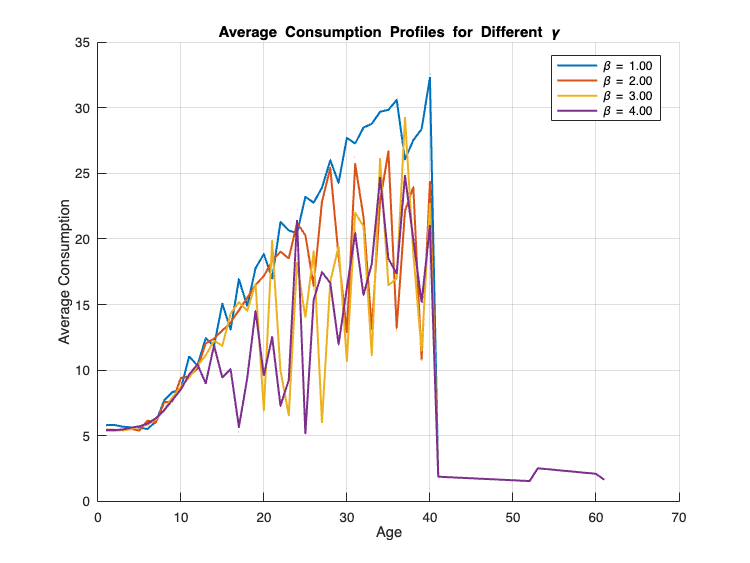


% Plot: Average Consumption
figure;
hold on;
colors = lines(length(gamma_list));
for b = 1:length(gamma_list)
    plot(1:T, avg_c_all(b, :), 'LineWidth', 1.5, 'Color', colors(b,:), ...
        'DisplayName', sprintf('\\beta = %.2f', gamma_list(b)));
end
hold off;
xlabel('Age');
ylabel('Average Consumption');
title('Average Consumption Profiles for Different \gamma');
legend('Location', 'best');
grid on;

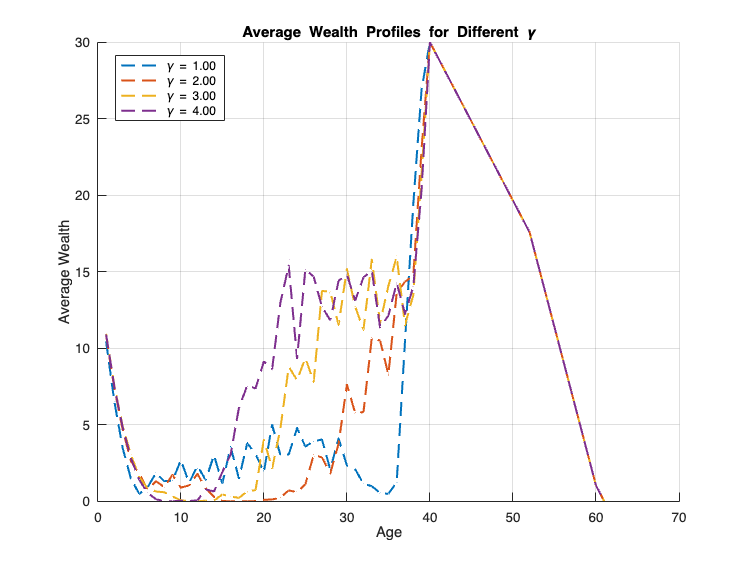


% Plot: Average Wealth
figure;
hold on;
for b = 1:length(gamma_list)
    plot(1:T, avg_a_all(b, :), '--', 'LineWidth', 1.5, 'Color', colors(b,:), ...
        'DisplayName', sprintf('\\gamma = %.2f', gamma_list(b)));
end
hold off;
xlabel('Age');
ylabel('Average Wealth');
title('Average Wealth Profiles for Different \gamma');
legend('Location', 'best');
grid on;


% === Descriptive Stats: Based on the Graph Data ===
table_beta_consumption = table();
table_beta_savings = table();

for b = 1:length(gamma_list)
    lcp_c = avg_c_all(b, :)';
    lcp_a = avg_a_all(b, :)';
    
    table_beta_consumption.Beta(b) = gamma_list(b);
    table_beta_consumption.Mean(b) = mean(lcp_c, 'omitnan');
    table_beta_consumption.Std(b) = std(lcp_c, 'omitnan');
    table_beta_consumption.Min(b) = min(lcp_c);
    table_beta_consumption.Max(b) = max(lcp_c);
    
    table_beta_savings.Beta(b) = gamma_list(b);
    table_beta_savings.Mean(b) = mean(lcp_a, 'omitnan');
    table_beta_savings.Std(b) = std(lcp_a, 'omitnan');
    table_beta_savings.Min(b) = min(lcp_a);
    table_beta_savings.Max(b) = max(lcp_a);
end


disp("Consumption Stats – Varying Gamma, Nu = 0.5");

Consumption Stats – Varying Gamma, Nu = 0.5


disp(table_beta_consumption);

    Beta     Mean      Std       Min       Max  
    ____    ______    ______    ______    ______

     1      12.523    10.548    1.5467    32.299
     2      10.449    8.2238    1.5467    26.672
     3      9.2267    7.3722    1.5467    29.246
     4      8.7313    6.8513    1.5467    24.836



disp("Wealth Stats – Varying Gamma, Nu = 0.5");

Wealth Stats – Varying Gamma, Nu = 0.5


disp(table_beta_savings);

    Beta     Mean      Std      Min     Max  
    ____    ______    ______    ___    ______

     1       8.661    9.4066     0         30
     2      8.8749    9.3895     0         30
     3      10.416    8.9929     0         30
     4      11.437    8.5212     0     29.999




%% === 2. GRAPHS: Varying Nu, Fixed Gamma = 2.00 ===
avg_c_all = nan(length(nu_list), T);
avg_a_all = nan(length(nu_list), T);

for b = 1:length(nu_list)
    par = model.setup();
    par.nu = nu_list(b);
    par.gamma = gamma_fixed;
    par = model.gen_grids(par);
    
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);
    
    for i = 1:T
        avg_c_all(b, i) = mean(sim.csim(sim.tsim == i), 'omitnan');
        avg_a_all(b, i) = mean(sim.asim(sim.tsim == i), 'omitnan');
    end
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


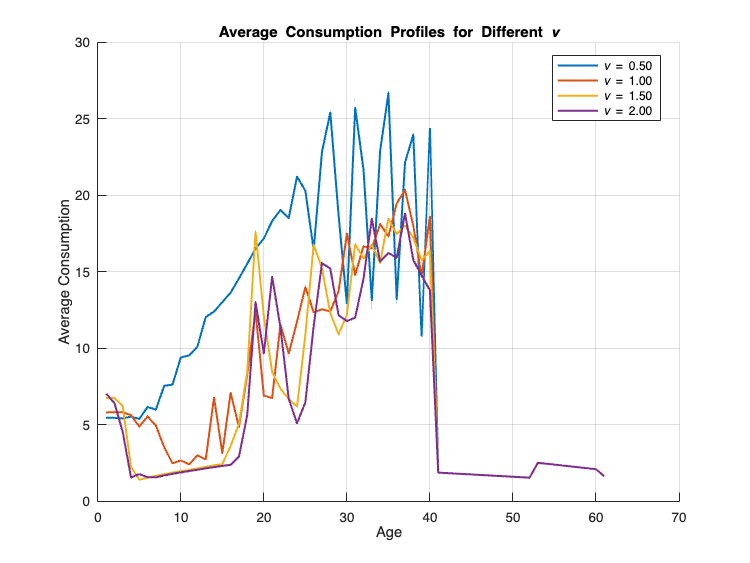


% Plot: Average Consumption
figure;
hold on;
colors = lines(length(nu_list));
for b = 1:length(nu_list)
    plot(1:T, avg_c_all(b, :), 'LineWidth', 1.5, 'Color', colors(b,:), ...
        'DisplayName', sprintf('\\nu = %.2f', nu_list(b)));
end
hold off;
xlabel('Age');
ylabel('Average Consumption');
title('Average Consumption Profiles for Different \nu');
legend('Location', 'best');
grid on;

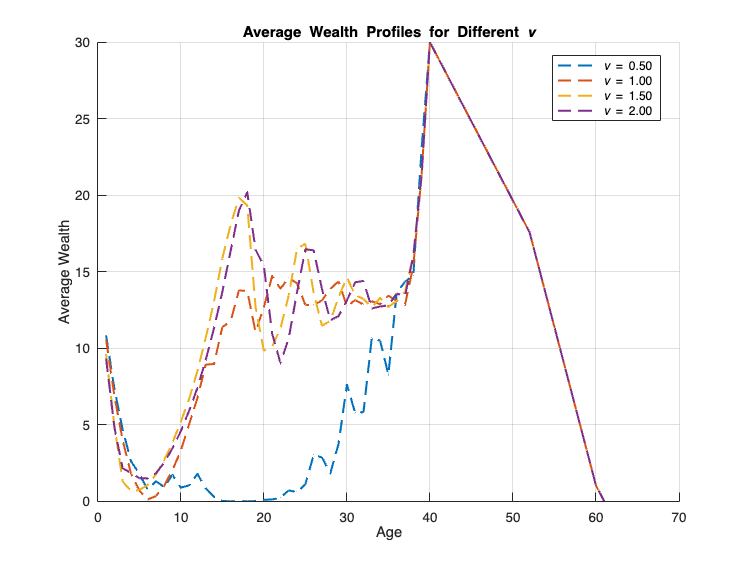


% Plot: Average Wealth
figure;
hold on;
for b = 1:length(nu_list)
    plot(1:T, avg_a_all(b, :), '--', 'LineWidth', 1.5, 'Color', colors(b,:), ...
        'DisplayName', sprintf('\\nu = %.2f', nu_list(b)));
end
hold off;
xlabel('Age');
ylabel('Average Wealth');
title('Average Wealth Profiles for Different \nu');
legend('Location', 'best');
grid on;


% === Descriptive Stats: Based on the Graph Data ===
table_gamma_consumption = table();
table_gamma_savings = table();

for b = 1:length(nu_list)
    lcp_c = avg_c_all(b, :)';
    lcp_a = avg_a_all(b, :)';
    
    table_gamma_consumption.Gamma(b) = nu_list(b);
    table_gamma_consumption.Mean(b) = mean(lcp_c, 'omitnan');
    table_gamma_consumption.Std(b) = std(lcp_c, 'omitnan');
    table_gamma_consumption.Min(b) = min(lcp_c);
    table_gamma_consumption.Max(b) = max(lcp_c);
    
    table_gamma_savings.Gamma(b) = nu_list(b);
    table_gamma_savings.Mean(b) = mean(lcp_a, 'omitnan');
    table_gamma_savings.Std(b) = std(lcp_a, 'omitnan');
    table_gamma_savings.Min(b) = min(lcp_a);
    table_gamma_savings.Max(b) = max(lcp_a);
end


disp("Consumption Stats – Varying Nu, Gamma = 2.00");

Consumption Stats – Varying Nu, Gamma = 2.00


disp(table_gamma_consumption);

    Gamma     Mean      Std       Min       Max  
    _____    ______    ______    ______    ______

     0.5     10.449    8.2238    1.5467    26.672
       1     7.2504    6.0237    1.5467    20.345
     1.5     6.6607    6.0849    1.4104    18.481
       2     6.2511    5.7415    1.5465    18.809




disp("Wealth Stats – Varying Nu, Gamma = 2.00");

Wealth Stats – Varying Nu, Gamma = 2.00


disp(table_gamma_savings);

    Gamma     Mean      Std      Min     Max  
    _____    ______    ______    ___    ______

     0.5     8.8749    9.3895     0         30
       1     12.718    7.6878     0         30
     1.5     13.187    7.7316     0     29.984
       2     13.169    7.7081     0     29.993



% === Load and Normalize Real Data ===
real_data = readtable("final_output.csv");

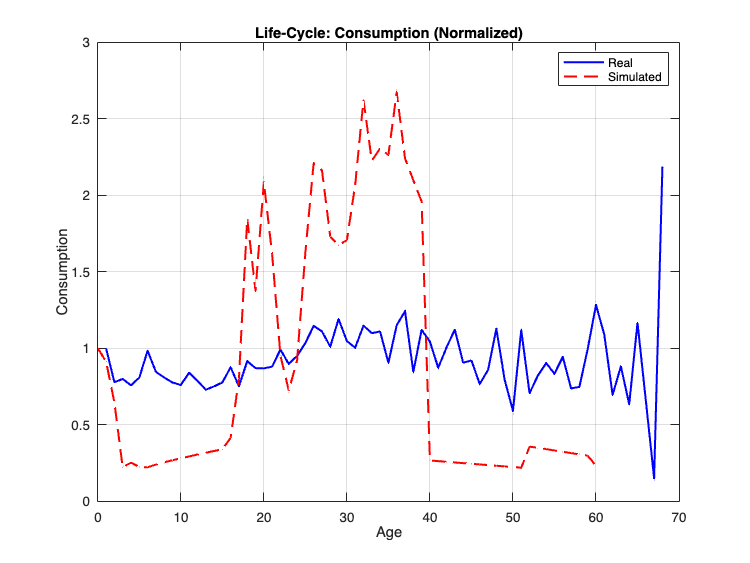


% Normalize 'age' to start from 0
[~, ~, age_idx] = unique(real_data.age);
real_data.age_norm = age_idx - 1;

% === Compute Lifecycle Profiles from Real Data ===
G = groupsummary(real_data, "age", "mean", ...
    ["avr_consumption", "total_wealth", "avg_working_hours_per_worker"]);

% Extract and rename relevant variables
real_profiles = table;
real_profiles.age        = G.age;
real_profiles.age = real_profiles.age - 24;
real_profiles.avg_cons   = G.mean_avr_consumption;
real_profiles.avg_wealth = G.mean_total_wealth;
real_profiles.avg_hours  = G.mean_avg_working_hours_per_worker / (260 * 16);  % Normalize hours

% Normalize consumption and wealth by age-0 values
real_profiles.avg_cons   = real_profiles.avg_cons / real_profiles.avg_cons(1);
real_profiles.avg_wealth = real_profiles.avg_wealth / real_profiles.avg_wealth(1);

% === Simulated Data ===
T = par.T;
sim_profiles = table((0:T-1)', 'VariableNames', {'age'});

% Initialize columns
sim_profiles.avg_cons   = zeros(T,1);
sim_profiles.avg_wealth = zeros(T,1);
sim_profiles.avg_hours  = zeros(T,1);

for t = 1:T
    idx = sim.tsim == t;
    sim_profiles.avg_cons(t)   = mean(sim.csim(idx), 'omitnan');
    sim_profiles.avg_wealth(t) = mean(sim.asim(idx), 'omitnan');
    sim_profiles.avg_hours(t)  = mean(sim.nsim(idx), 'omitnan');
end

% Normalize simulated consumption
sim_profiles.avg_cons = sim_profiles.avg_cons / sim_profiles.avg_cons(1);

% === Plot 1: Consumption (Normalized) ===
figure;
plot(real_profiles.age, real_profiles.avg_cons, 'b-', 'LineWidth', 1.5); hold on;
plot(sim_profiles.age, sim_profiles.avg_cons, 'r--', 'LineWidth', 1.5);
title('Life-Cycle: Consumption (Normalized)');
xlabel('Age'); ylabel('Consumption');
legend('Real', 'Simulated'); grid on;

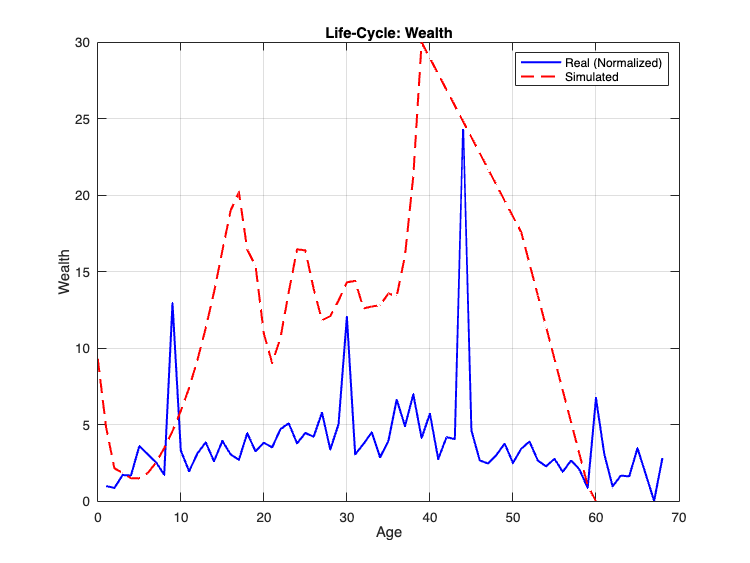


% === Plot 2: Wealth (Real = Normalized, Sim = Raw) ===
figure;
plot(real_profiles.age, real_profiles.avg_wealth, 'b-', 'LineWidth', 1.5); hold on;
plot(sim_profiles.age, sim_profiles.avg_wealth, 'r--', 'LineWidth', 1.5);
title('Life-Cycle: Wealth');
xlabel('Age'); ylabel('Wealth');
legend('Real (Normalized)', 'Simulated'); grid on;

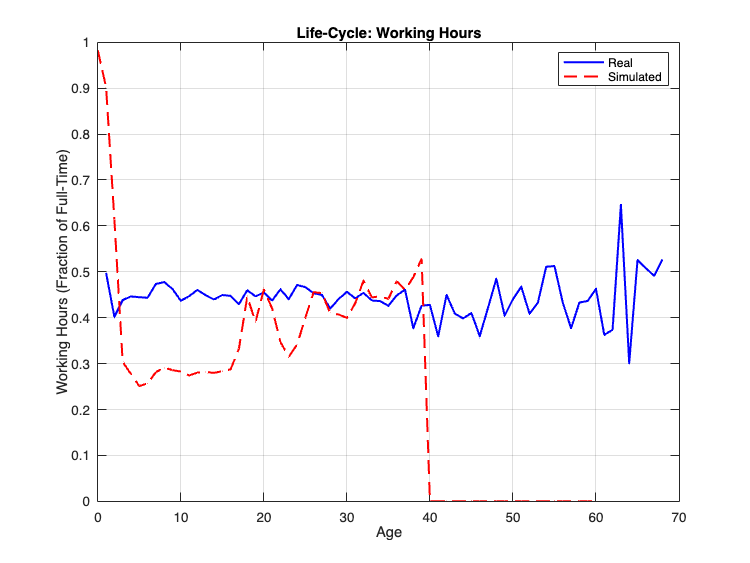


% === Plot 3: Working Hours (Normalized by 240) ===
figure;
plot(real_profiles.age, real_profiles.avg_hours, 'b-', 'LineWidth', 1.5); hold on;
plot(sim_profiles.age, sim_profiles.avg_hours, 'r--', 'LineWidth', 1.5);
title('Life-Cycle: Working Hours');
xlabel('Age'); ylabel('Working Hours (Fraction of Full-Time)');
legend('Real', 'Simulated'); grid on;

% Descriptive Statistics for Real Data 
% === Compute Summary Statistics for Real Data ===
real_summary = [
    mean(real_profiles.avg_cons), std(real_profiles.avg_cons);
    mean(real_profiles.avg_wealth), std(real_profiles.avg_wealth);
    mean(real_profiles.avg_hours), std(real_profiles.avg_hours)
];

% === Compute Summary Statistics for Simulated Data ===
sim_summary = [
    mean(sim_profiles.avg_cons), std(sim_profiles.avg_cons);
    mean(sim_profiles.avg_wealth), std(sim_profiles.avg_wealth);
    mean(sim_profiles.avg_hours), std(sim_profiles.avg_hours)
];

% === Assemble Table ===
row_labels = {'Consumption'; 'Wealth'; 'Working Hours'};
stats_table = array2table([real_summary sim_summary], ...
    'VariableNames', {'Mean_Real', 'Std_Real', 'Mean_Sim', 'Std_Sim'}, ...
    'RowNames', row_labels);

% === Display Result ===
disp('Descriptive Statistics Comparison');

Descriptive Statistics Comparison


disp(stats_table);

                     Mean_Real    Std_Real    Mean_Sim    Std_Sim
                     _________    ________    ________    _______

    Consumption       0.92966      0.24023    0.88846     0.81604
    Wealth             3.9037        3.291     13.169      7.7081
    Working Hours     0.44294     0.046615    0.26547     0.23005

